# Problem 6

%%% Loading fruit images %%%
images = [];
for i = 1:16
    img = imread('../data/data_fruit/image_'+string(i)+'.png');
    imgvec = cast(img(:),'double');
    images = [images imgvec];
end

mean = sum(images,2)/16

mean =   128.1875
  130.0625
  131.6250
  129.2500
  130.8125
  133.5625
  132.8750
  132.6875
  134.1875
  136.6875


save("mean.mat","mean")

covariance = zeros(19200,19200,'double');
for i = 1:16
    covariance = covariance + (images(:,i)-mean)*(images(:,i)-mean).';
end
covariance = covariance/16

covariance = 	1.0e+03 *

    7.7434    7.6126    7.5899    7.6230    7.6043    7.4660    7.2556    7.1444    7.1482    6.9560    6.4715    6.2570    6.4481    6.6200    6.4409    5.7461    4.9739    4.3340    3.7256    3.1809    2.2651    1.8096    1.6820    1.3232    0.8554    0.4735   -0.0389   -0.6817   -1.3277   -1.7939   -1.9471   -1.9128   -1.8951   -1.9239   -2.0945   -2.1925   -2.1936   -2.3102   -2.1895   -2.3744   -2.2114   -1.9535   -2.0354   -2.0313   -1.8275   -1.5675   -1.0266   -0.8374   -0.6487   -0.4379
    7.6126    7.5083    7.4932    7.4966    7.4821    7.3455    7.1186    7.0068    7.0209    6.8338    6.3512    6.1353    6.3329    6.5182    6.3246    5.6479    4.8894    4.2782    3.6716    3.1244    2.2364    1.7688    1.6507    1.2647    0.7870    0.4134   -0.0975   -0.7075   -1.3111   -1.7527   -1.8948   -1.8591   -1.8400   -1.8619   -2.0304   -2.1348   -2.1438   -2.2593   -2.1300   -2.3190   -2.1478   -1.8854   -1.9660   -1.9631   -1.7606   -1.4943   -0.9447   -

save("covariance.mat","covariance")

%%% PART1 %%%
[Q,D] = eigs(covariance,10);
d = diag(D)

d = 	1.0e+07 *

    1.3107
    1.2185
    0.8753
    0.5687
    0.4221
    0.2818
    0.2499
    0.1823
    0.1531
    0.1172


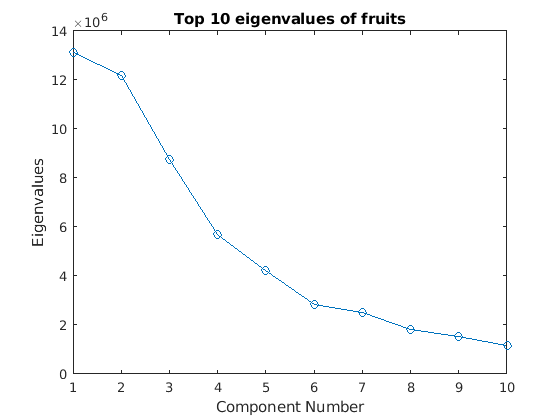

plt = plot(d,'marker',"o");
ylabel("Eigenvalues");
xlabel("Component Number");
title("Top 10 eigenvalues of fruits");
saveas(plt,"eigenvalues","png");

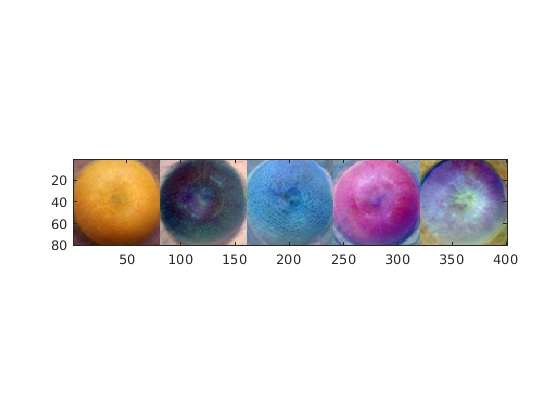

save("eigenvalues.mat","d");

mean_image = reshape(mean,80,80,3);
mean_image = rescale(mean_image);

img1 = reshape(Q(:,1),80,80,3);
img1 = rescale(img1);

img2 = reshape(Q(:,2),80,80,3);
img2 = rescale(img2);

img3 = reshape(Q(:,3),80,80,3);
img3 = rescale(img3);

img4 = reshape(Q(:,4),80,80,3);
img4 = rescale(img4);

img = image([mean_image img1 img2 img3 img4]);
daspect([1 1 1])
saveas(img,"fruits","png")

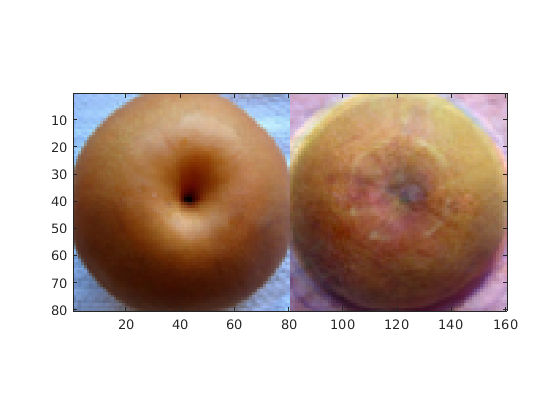

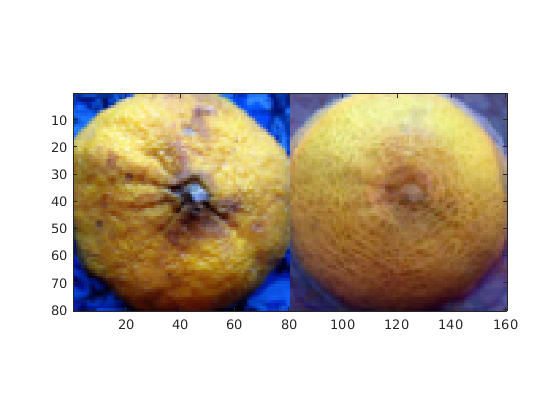

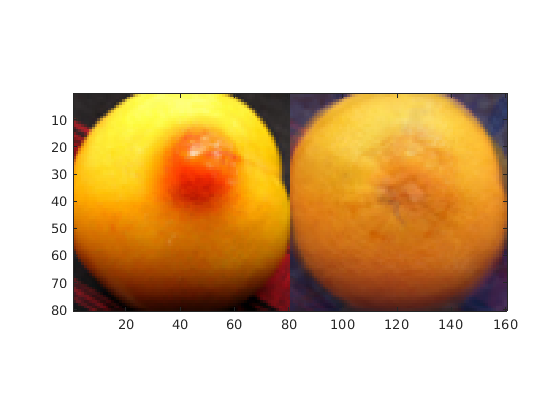

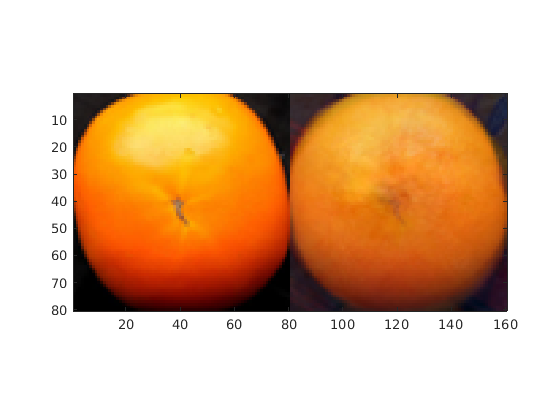

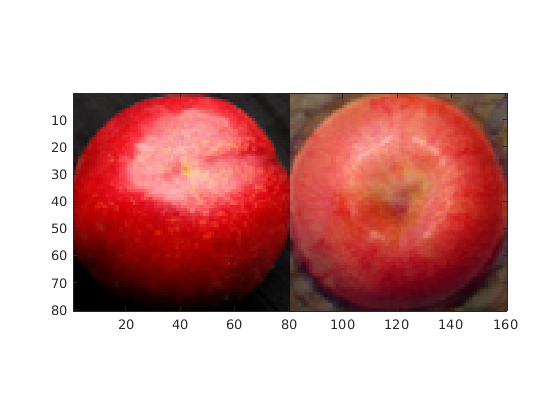

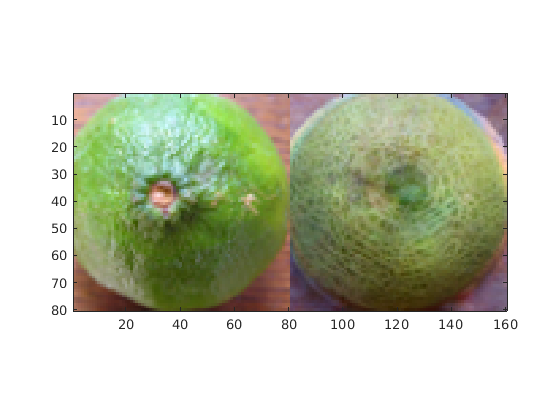

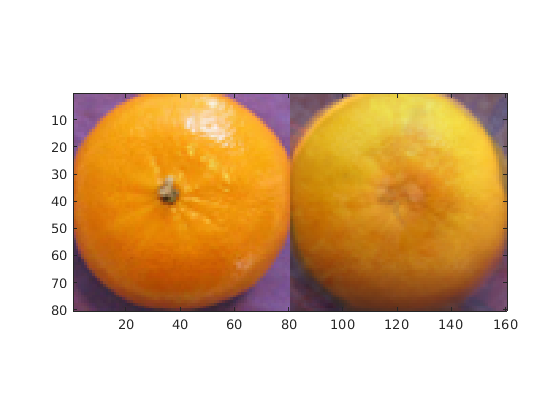

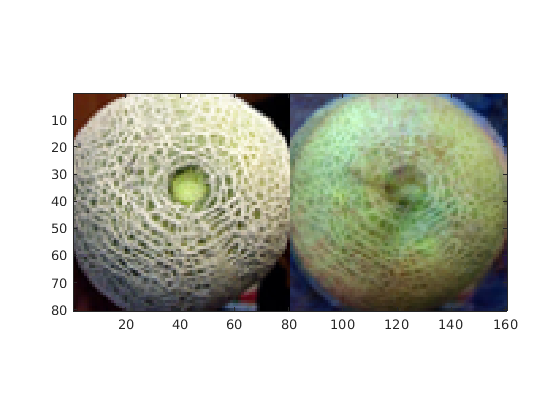

%%% PART2 %%%
for i = 1:16
    img = imread('../data/data_fruit/image_'+string(i)+'.png');
    imgvec = cast(img(:),'double');
    imgvec = imgvec - mean;
    clst_img = (imgvec.'*Q(:,1)).*Q(:,1) + (imgvec.'*Q(:,2)).*Q(:,2) + (imgvec.'*Q(:,3)).*Q(:,3) + (imgvec.'*Q(:,4)).*Q(:,4) + mean;
    clst_img = reshape(clst_img,80,80,3);
    clst_img = rescale(clst_img);
    figure
    final_image = image([rescale(img) clst_img]);
    daspect([1 1 1]);
    drawnow
    saveas(final_image,'closest' + string(i),'png');
end

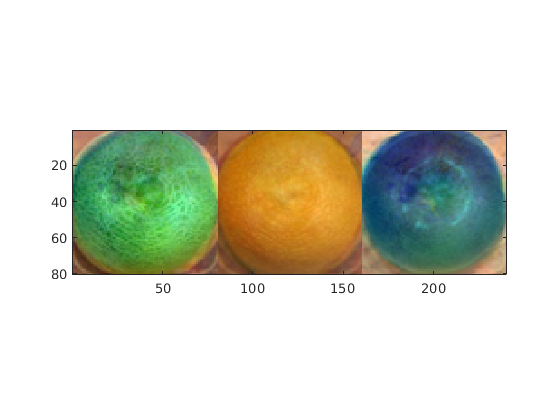

%%% PART3 %%%
rng(0)
W  = randn(4,3);
A = Q(:,1:4)*diag(sqrt(d(1:4)));
X = A*W + mean;

new_fruit1 = reshape(X(:,1),80,80,3);
new_fruit1 = rescale(new_fruit1);

new_fruit2 = reshape(X(:,2),80,80,3);
new_fruit2 = rescale(new_fruit2);

new_fruit3 = reshape(X(:,3),80,80,3);
new_fruit3 = rescale(new_fruit3);

img2 = image([new_fruit1 new_fruit2 new_fruit3]);
daspect([1 1 1]);
saveas(img2,"new_fruits","png")